t = 0:0.01:100;
s = tf('s');
G = (1-s)* exp(-s) /((12*s+1)*(3*s+1)*(0.2*s+1)*(0.05*s+1));

G1 = 1/(18 * s + 1)

G1 =
 
     1
  --------
  18 s + 1
 
Continuous-time transfer function.



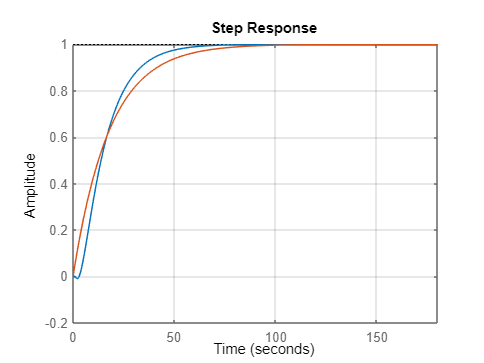

figure 
step(G)
grid on
hold on
step(G1)

[y1, ~] = step(G, t);
[y2, ~] = step(G1, t);

mse = mean((y1 - y2).^2);
disp(['Mean Squared Error: ', num2str(mse)]);

Mean Squared Error: 0.0029543


G2 = 1/(17.5 * s + 1)

G2 =
 
      1
  ----------
  17.5 s + 1
 
Continuous-time transfer function.



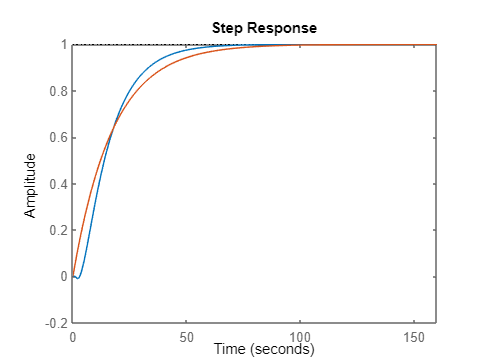

figure 
step(G)
hold on
step(G2)

[y1, ~] = step(G, t);
[y2, ~] = step(G2, t);

mse = mean((y1 - y2).^2);

disp(['Mean Squared Error: ', num2str(mse)]);

Mean Squared Error: 0.0029226


G3 = 1/(12.645 * s + 1)

G3 =
 
       1
  -----------
  12.64 s + 1
 
Continuous-time transfer function.



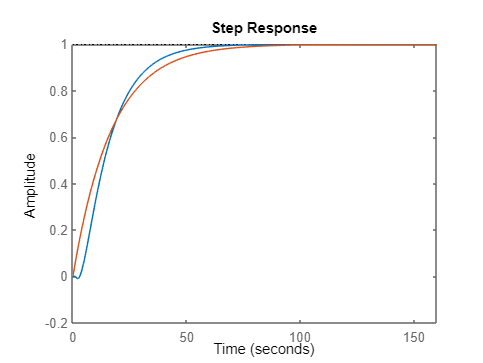

figure
step(G)
hold on
step(G4_delay)

[y1, ~] = step(G, t);
[y2, ~] = step(G3, t);

mse = mean((y1 - y2).^2);

disp(['Mean Squared Error: ', num2str(mse)]);

Mean Squared Error: 0.0076472


G4 = 1/(18 * s + 1)

G4 =
 
     1
  --------
  18 s + 1
 
Continuous-time transfer function.



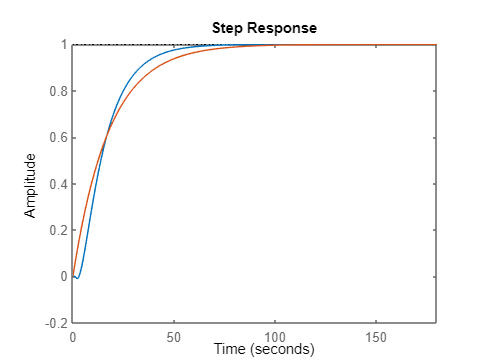

figure
step(G)
hold on
step(G4)

[y1, ~] = step(G, t);
[y2, ~] = step(G4, t);

mse = mean((y1 - y2).^2);

disp(['Mean Squared Error: ', num2str(mse)]);

Mean Squared Error: 0.0029543


G4_delay = 1/(17 * s + 1)

G4_delay =
 
     1
  --------
  17 s + 1
 
Continuous-time transfer function.



figure
step(G)
hold on
step(G4_delay)

[y1, ~] = step(G, t);
[y2, ~] = step(G4_delay, t);

mse = mean((y1 - y2).^2);

disp(['Mean Squared Error: ', num2str(mse)]);

Mean Squared Error: 0.0029736


G5 = exp(-s)/(8.5 * s + 1)^2 %%critical damping

G5 =
 
                       1
  exp(-1*s) * --------------------
              72.25 s^2 + 17 s + 1
 
Continuous-time transfer function.



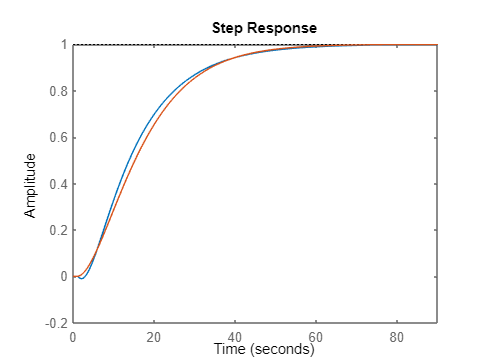

figure
step(G)
hold on
step(G5)

[y1, ~] = step(G, t);
[y2, ~] = step(G5, t);

mse = mean((y1 - y2).^2);

disp(['Mean Squared Error: ', num2str(mse)]);

Mean Squared Error: 0.00039667


G6 = exp(-s)/((27.3 * s + 1)*(5.03 * s + 1))

G6 =
 
                         1
  exp(-1*s) * -----------------------
              137.3 s^2 + 32.33 s + 1
 
Continuous-time transfer function.



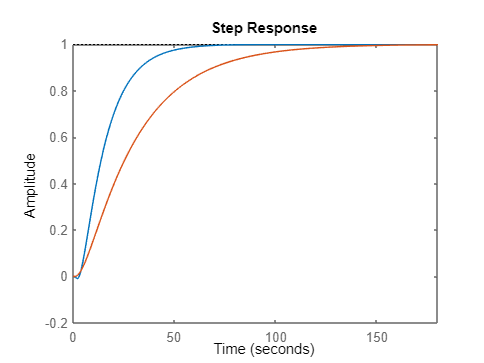

figure
step(G)
hold on
step(G6)

[y1, ~] = step(G, t);
[y2, ~] = step(G6, t);

mse = mean((y1 - y2).^2);

disp(['Mean Squared Error: ', num2str(mse)]);

Mean Squared Error: 0.032654
